### 1. Ejemplo: Iris dataset (PCA aplicado antes)

Se aplicó PCA al dataset de Iris (Para poder visualizarlo en 2D). Las clases aquí son 3 tipos de flor

#### 1.1. Visualización de los datos 

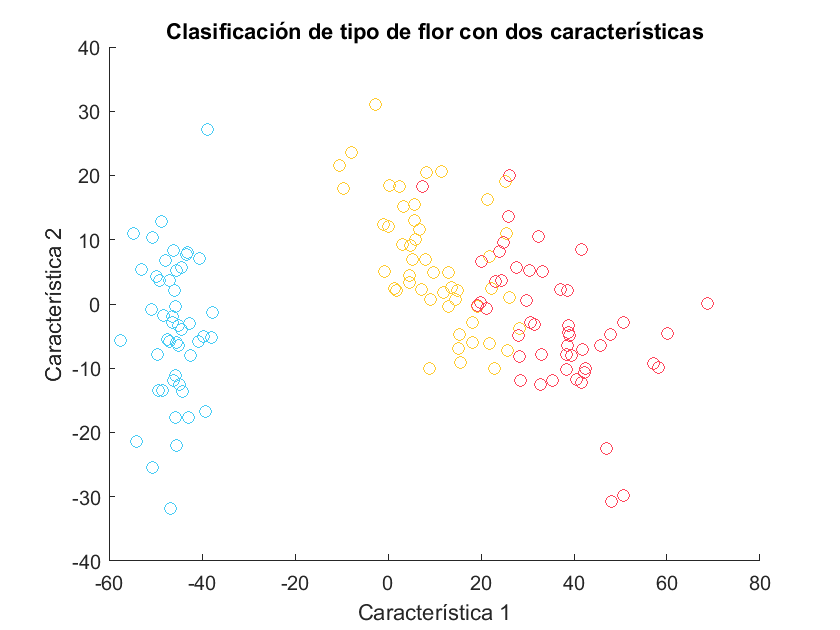

data = importdata('flower_pca_data.csv', ",");
flowerData = data(:,1:2);
flowerClass = data(:,3)+1;
n = size(flowerData,1);
color1 = [71/255,204/255,245/255];
color2 = [255/255, 203/255, 48/255];
color3 = [255/255, 69/255, 91/255];
figure()
hold on 
for i = 1:n
    point = flowerData(i,:);
    if(flowerClass(i) == 1)
        plot(point(1), point(2), 'Color',color1,'Marker', 'o')
    elseif(flowerClass(i) == 2)
        plot(point(1), point(2), 'Color', color2, 'Marker','o')
    elseif(flowerClass(i) == 3)
        plot(point(1), point(2), 'Color',color3, 'Marker','o')
    end
end
title("Clasificación de tipo de flor con dos características")
xlabel("Característica 1")
ylabel("Característica 2")
hold off

#### 1.2. Frontera de decisión para distintos valores de k

%Examinemos la clasificación para números distint
dataCooker = DataPrecook();
[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(flowerData, flowerClass, 0.1);
kValues  = [1,2,3,6,10,15];
gridSize = 100;
xGridArray = linspace(min(trainData(:,1)), max(trainData(:,1)), gridSize);
yGridArray = linspace(min(trainData(:,2)), max(trainData(:,2)), gridSize);
[xGrid, yGrid]  = meshgrid(xGridArray, yGridArray);
disp("here");

here


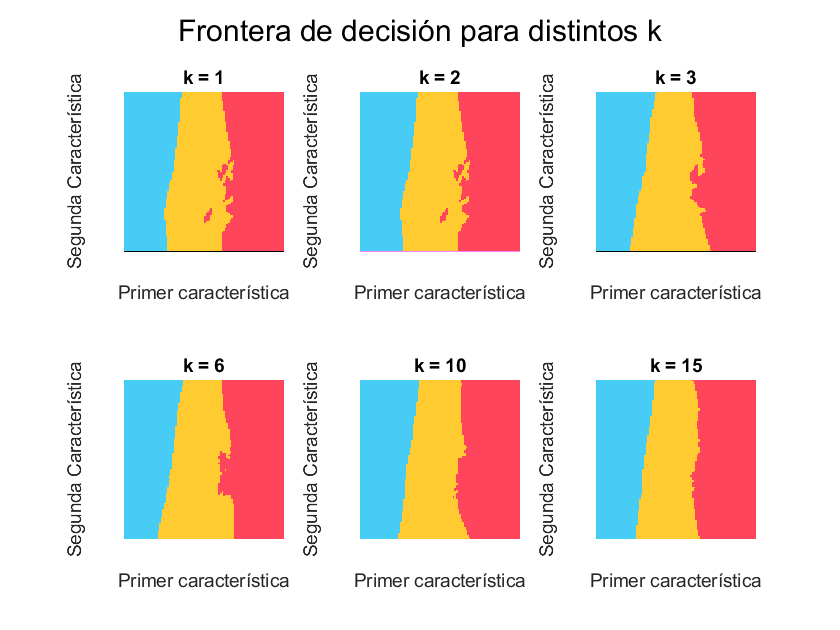

f = waitbar(0,'Procesando');
figure()
sgtitle("Frontera de decisión para distintos k")
hold on 
for i = 1:length(kValues)
    kValue = kValues(i);
    waitbar(i/length(kValues),f, "Procesando");
    classificationGrid = zeros(gridSize, gridSize, 3);
    %Creamos un clasificador
    knnClassifier = KNNClassifier(trainData, trainDataClass, kValue, MetricType.EUCLIDEAN);
    for j = 1:gridSize
        for k = 1:gridSize
           class = knnClassifier.classify([xGrid(j,k), yGrid(j,k)]); 
           if(class == 1)
               classificationGrid(j,k,:) = color1;
           elseif(class == 2)
               classificationGrid(j,k,:) = color2;
           elseif(class == 3)
               classificationGrid(j,k,:) = color3;
           end
         end
    end
    subplot(2,3,i)
    imshow(classificationGrid)
    title("k = "+string(kValue))
    xlabel("Primer característica")
    ylabel("Segunda Característica")
end
close(f);
hold off

#### 1.3. Curva de accuracy para distintos valores de k

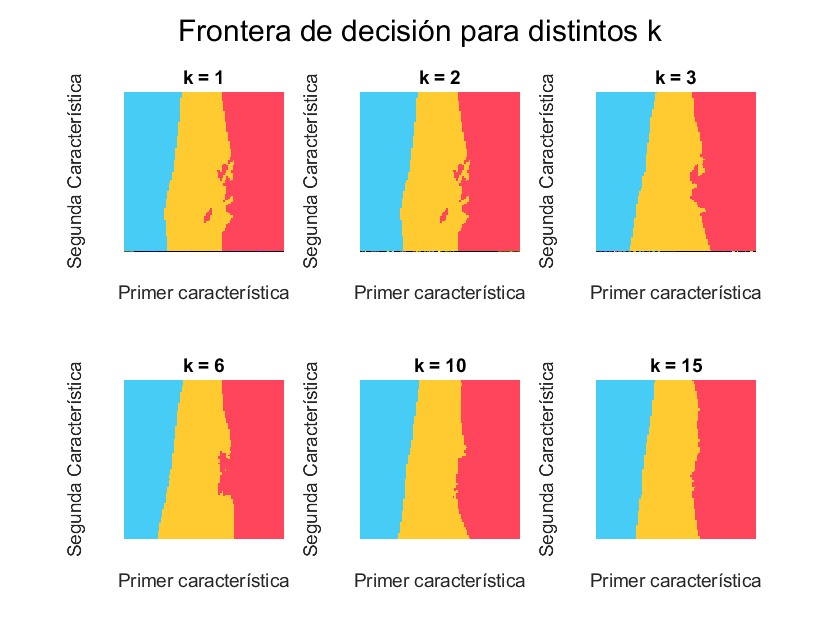

kValues = 1:20;
accuracies = zeros(length(kValues), 1);
classToConsider = 2;
nExp = 200;

accCalcu = AccuracyCalculator();
f = waitbar(0,'Procesando');
for i = 1:length(kValues)
    kValue = kValues(i);
    accuracy = 0;
    waitbar(i/length(kValues),f, "Procesando");
    for s = 1:nExp
    [trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(flowerData, flowerClass, 0.2);
    knnClassifier = KNNClassifier(trainData, trainDataClass, kValue, MetricType.EUCLIDEAN);
    tp = 0;
    fp = 0;
    tn = 0;
    fn = 0;
    for j = 1:size(valData,1)
        vector = valData(j,:);
        class = valDataClass(j);
        predictedClass = knnClassifier.classify(vector);
        if(predictedClass == classToConsider && class == classToConsider)
            tp = tp + 1;
        elseif(predictedClass ~= classToConsider && class == classToConsider)
            fn = fn + 1;
        elseif(predictedClass ~= classToConsider && class ~= classToConsider)
            tn = tn + 1;
        elseif(predictedClass == classToConsider && class ~= classToConsider)
            fp = fp +1;
        end
    end
    accuracy = accuracy + (1/nExp)*accCalcu.calculateAccuracy(tp, fp, tn, fn);
    end
    accuracies(i) = accuracy;
end

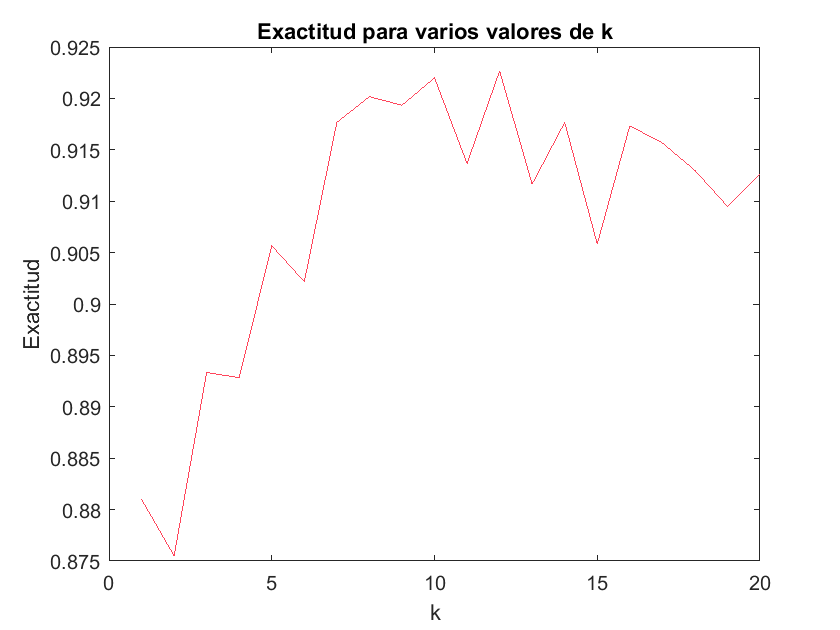

close(f);
figure()
plot(kValues, accuracies, 'Color', color3)
title("Exactitud para varios valores de k")
xlabel("k")
ylabel("Exactitud")

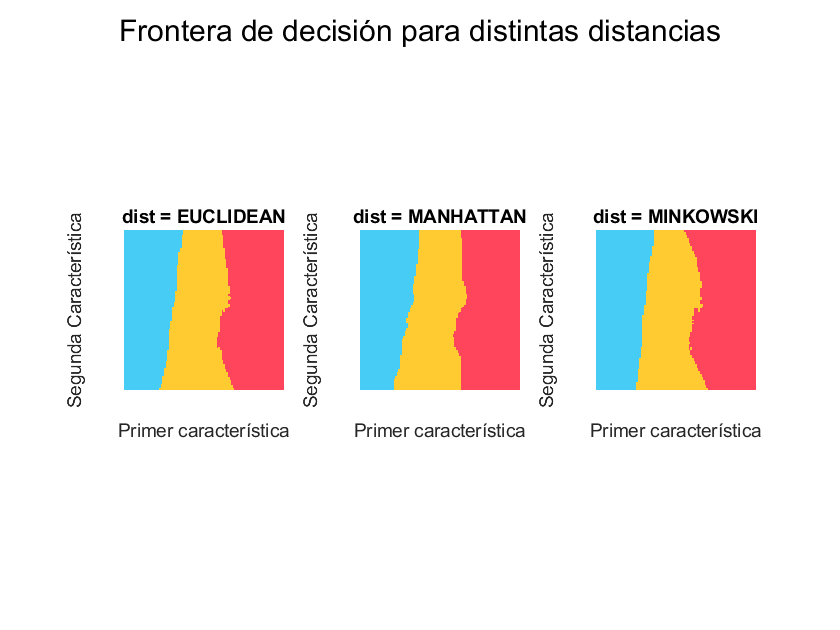

%Examinemos la clasificación para números distint
dataCooker = DataPrecook();
[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(flowerData, flowerClass, 0.1);
metrics  = [MetricType.EUCLIDEAN, MetricType.MANHATTAN, MetricType.MINKOWSKI];
gridSize = 100;
xGridArray = linspace(min(trainData(:,1)), max(trainData(:,1)), gridSize);
yGridArray = linspace(min(trainData(:,2)), max(trainData(:,2)), gridSize);
[xGrid, yGrid]  = meshgrid(xGridArray, yGridArray);
f = waitbar(0,'Procesando');
figure()
sgtitle("Frontera de decisión para distintas distancias")
hold on 
for i = 1:length(metrics)
    metric = metrics(i);
    waitbar(i/length(metrics),f, "Procesando");
    classificationGrid = zeros(gridSize, gridSize, 3);
    %Creamos un clasificador
    knnClassifier = KNNClassifier(trainData, trainDataClass, 7, metric);
    for j = 1:gridSize
        for k = 1:gridSize
           class = knnClassifier.classify([xGrid(j,k), yGrid(j,k)]); 
           if(class == 1)
               classificationGrid(j,k,:) = color1;
           elseif(class == 2)
               classificationGrid(j,k,:) = color2;
           elseif(class == 3)
               classificationGrid(j,k,:) = color3;
           end
         end
    end
    subplot(1,3,i)
    imshow(classificationGrid)
    title("dist = "+string(metric))
    xlabel("Primer característica")
    ylabel("Segunda Característica")
end
close(f);
hold off

kValues = 1:20;
classToConsider = 3;
nExp =100;
metrics  = [MetricType.EUCLIDEAN, MetricType.MANHATTAN, MetricType.MINKOWSKI];
accuracies = zeros(length(metrics), 1);
metricNames = categorical({'Euclidiana', 'Manhattan', 'Minkowski'});
metricNames = reordercats(metricNames,{'Euclidiana', 'Manhattan', 'Minkowski'});
accCalcu = AccuracyCalculator();
f = waitbar(0,'Procesando');
for i = 1:length(metrics)
    metric = metrics(i);
    accuracy = 0;
    waitbar(i/length(metrics),f, "Procesando");
    for s = 1:nExp
    [trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(flowerData, flowerClass, 0.1);
    knnClassifier = KNNClassifier(trainData, trainDataClass, 7, metric);
    tp = 0;
    fp = 0;
    tn = 0;
    fn = 0;
    for j = 1:size(valData,1)
        vector = valData(j,:);
        class = valDataClass(j);
        predictedClass = knnClassifier.classify(vector);
        if(predictedClass == classToConsider && class == classToConsider)
            tp = tp + 1;
        elseif(predictedClass ~= classToConsider && class == classToConsider)
            fn = fn + 1;
        elseif(predictedClass ~= classToConsider && class ~= classToConsider)
            tn = tn + 1;
        elseif(predictedClass == classToConsider && class ~= classToConsider)
            fp = fp +1;
        end
    end
    accuracy = accuracy + (1/nExp)*accCalcu.calculateAccuracy(tp, fp, tn, fn);
    end
    accuracies(i) = accuracy;
end

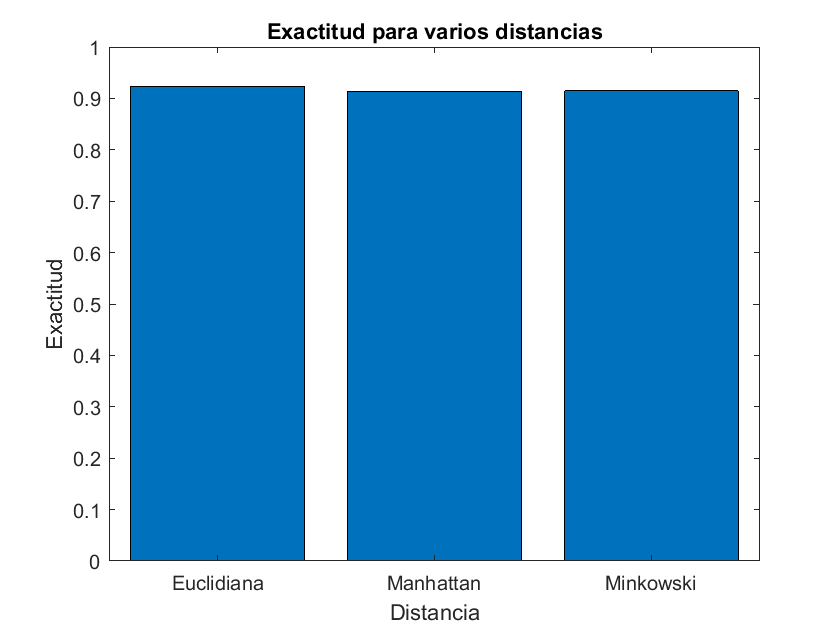

close(f);
figure()
bar(metricNames, accuracies)
title("Exactitud para varios distancias")
xlabel("Distancia")
ylabel("Exactitud")

accuracies

accuracies =     0.9227
    0.9133
    0.9147


#### 3. Ejemplo de regresión

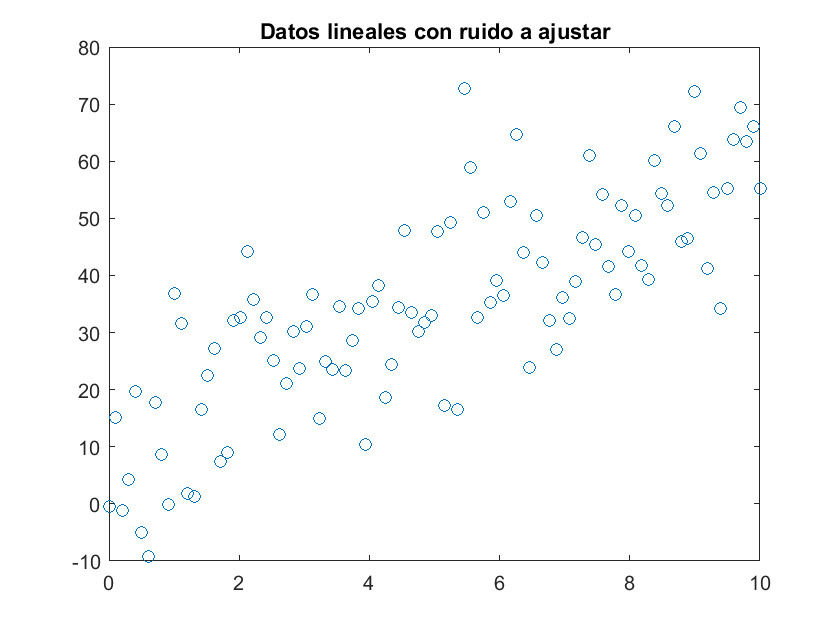

x = linspace(0,10,100);
y = 5*x + 10;
y = awgn(y,10,'measured');
figure()
plot(x,y, 'o')
title("Datos lineales con ruido a ajustar")

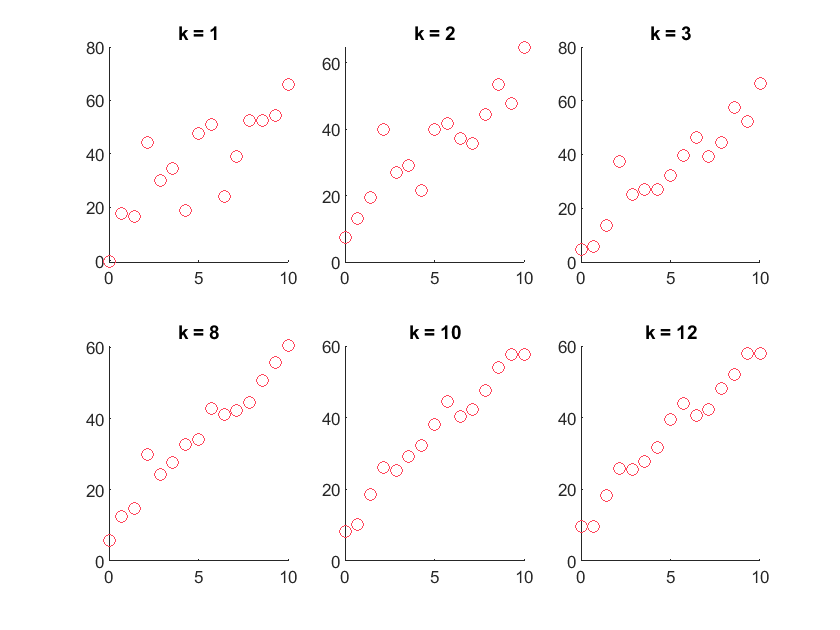

%Creamos el objeto para hacer regresion
[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = [1,2, 3, 8, 10, 12];
xSample = linspace(0,10,15);
figure()
for j = 1:length(kValues)
kValue = kValues(j);
knnRegression = KNNRegression(trainData,trainDataClass,kValue,MetricType.EUCLIDEAN);
subplot(2,3,j)
hold on 
for i = 1:length(xSample)
    xVal = xSample(i);
    yVal = knnRegression.regression(xVal);
    plot(xVal, yVal,'o','Color', color3)
end
title("k = "+string(kValue))
hold off
end

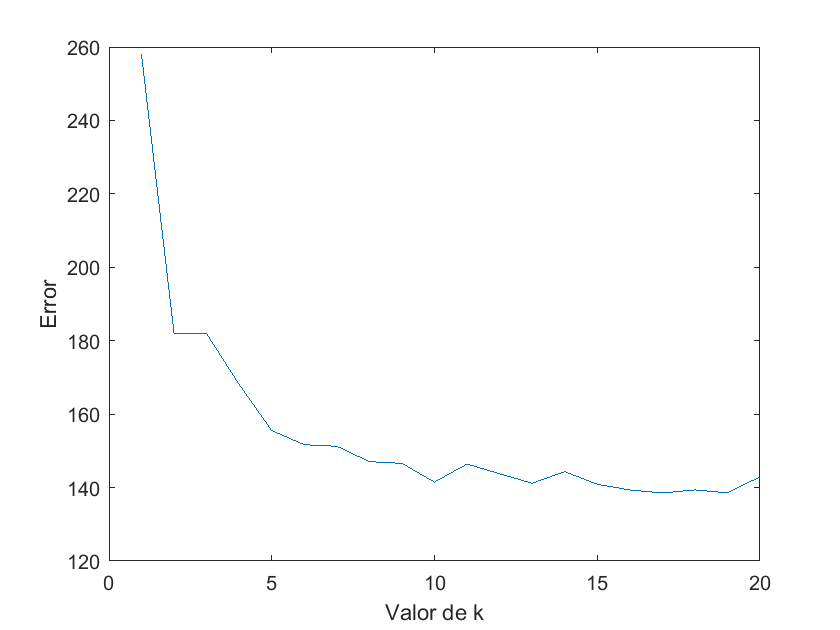


knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = 1:20;
xSample = linspace(0,10,15);
nExp = 1000;
errors = zeros(length(kValues), 1);
f = waitbar(0,'Procesando');
for j = 1:length(kValues)
    waitbar(j/length(kValues),f, "Procesando");
    kValue = kValues(j);
    error = 0;
    for i = 1:nExp
        [trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
        knnRegression = KNNRegression(trainData,trainDataClass,kValue,MetricType.EUCLIDEAN);
        err = 0;
        for t = 1:length(valData)
            xVal = valData(t);
            yVal = knnRegression.regression(xVal);
            err  = err +(1/length(valData))*(yVal - valDataClass(t))^2;
        end
        error  = error + (1/nExp)*err;
    end
    errors(j) = error; 
end
close(f)
figure()
plot(kValues, errors)
ylabel("Error")
xlabel("Valor de k")

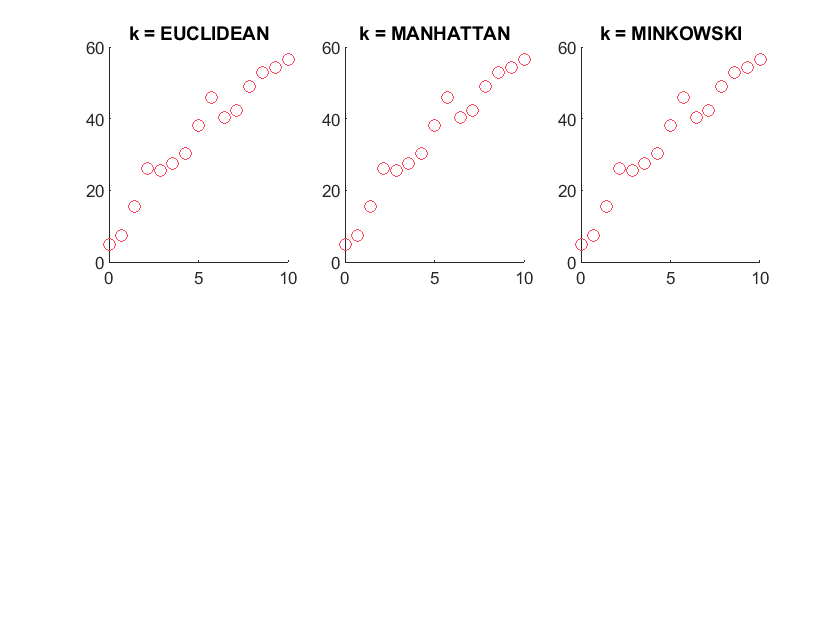

[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = [MetricType.EUCLIDEAN, MetricType.MANHATTAN, MetricType.MINKOWSKI];
xSample = linspace(0,10,15);
figure()
for j = 1:length(kValues)
kValue = kValues(j);
knnRegression = KNNRegression(trainData,trainDataClass,10,kValue);
subplot(2,3,j)
hold on 
for i = 1:length(xSample)
    xVal = xSample(i);
    yVal = knnRegression.regression(xVal);
    plot(xVal, yVal,'o','Color', color3)
end
title("k = "+string(kValue))
hold off
end

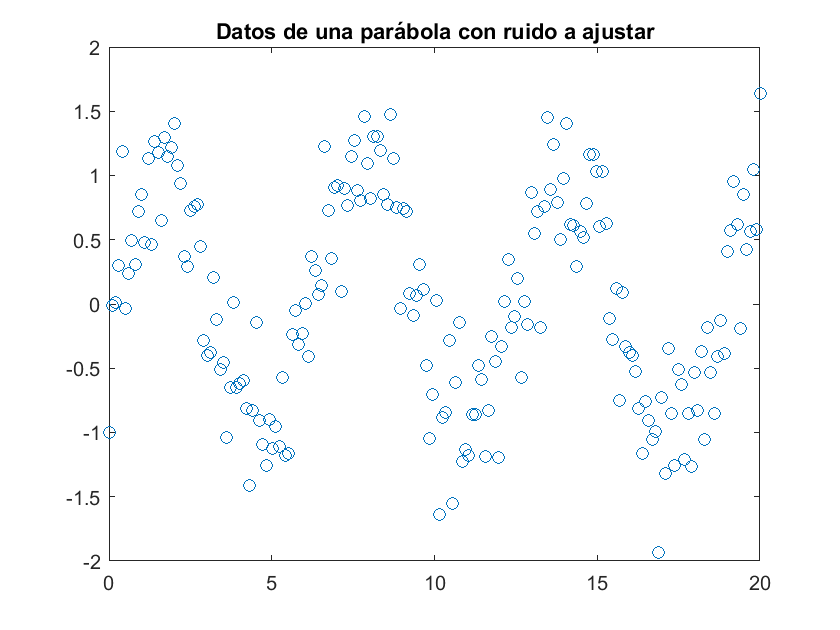

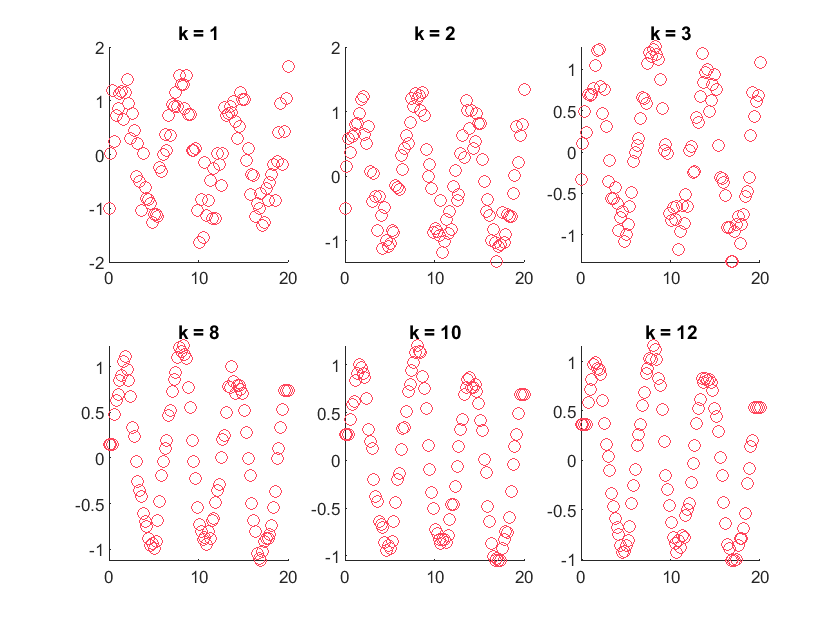

x = linspace(0,20,200);
y = sin(x);
y = awgn(y,5,'measured');
figure()
plot(x,y, 'o')
title("Datos de una función seno con ruido a ajustar")
[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = [1,2, 3, 8, 10, 12];
xSample = linspace(0,20,100);
figure()
for j = 1:length(kValues)
kValue = kValues(j);
knnRegression = KNNRegression(trainData,trainDataClass,kValue,MetricType.EUCLIDEAN);
subplot(2,3,j)
hold on 
for i = 1:length(xSample)
    xVal = xSample(i);
    yVal = knnRegression.regression(xVal);
    plot(xVal, yVal,'o','Color', color3)
end
title("k = "+string(kValue))
hold off
end

knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = 1:20;
xSample = linspace(0,10,15);
nExp = 1000;
errors = zeros(length(kValues), 1);
f = waitbar(0,'Procesando');
for j = 1:length(kValues)
    waitbar(j/length(kValues),f, "Procesando");
    kValue = kValues(j);
    error = 0;
    for i = 1:nExp
        [trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
        knnRegression = KNNRegression(trainData,trainDataClass,kValue,MetricType.EUCLIDEAN);
        err = 0;
        for t = 1:length(valData)
            xVal = valData(t);
            yVal = knnRegression.regression(xVal);
            err  = err +(1/length(valData))*(yVal - valDataClass(t))^2;
        end
        error  = error + (1/nExp)*err;
    end
    errors(j) = error; 
end

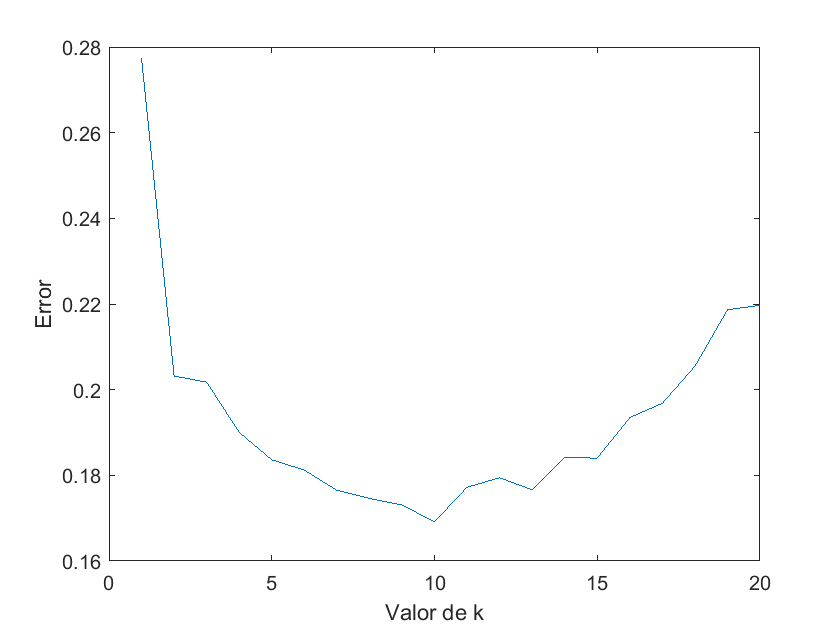

close(f)
figure()
plot(kValues, errors)
ylabel("Error")
xlabel("Valor de k")

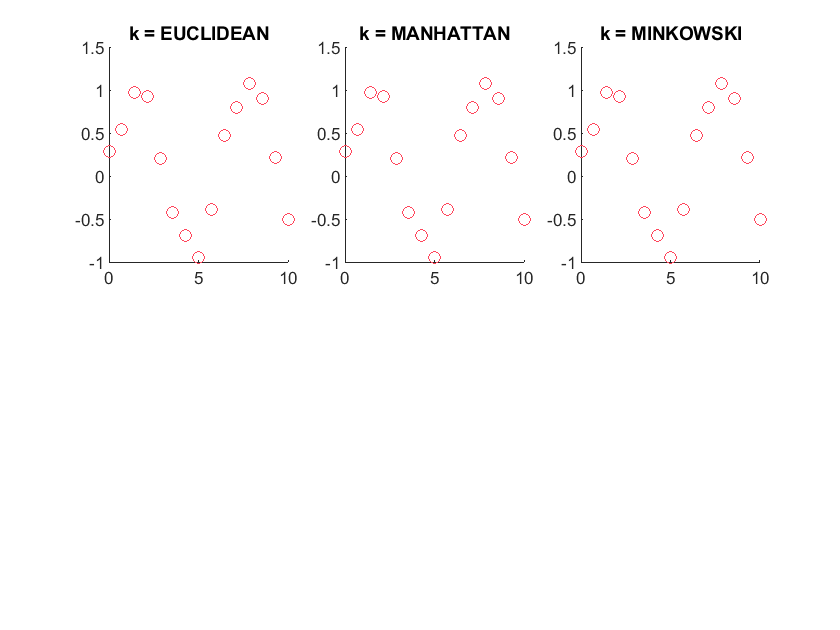

[trainData, trainDataClass, valData, valDataClass] = dataCooker.splitData(x',y', 0.1);
knnRegression = KNNRegression(trainData,trainDataClass,8,MetricType.EUCLIDEAN);
kValues = [MetricType.EUCLIDEAN, MetricType.MANHATTAN, MetricType.MINKOWSKI];
xSample = linspace(0,10,15);
figure()
for j = 1:length(kValues)
kValue = kValues(j);
knnRegression = KNNRegression(trainData,trainDataClass,10,kValue);
subplot(2,3,j)
hold on 
for i = 1:length(xSample)
    xVal = xSample(i);
    yVal = knnRegression.regression(xVal);
    plot(xVal, yVal,'o','Color', color3)
end
title("k = "+string(kValue))
hold off
end